% Test For first sound

% Sound captured in Diwali Noise
% Reading the audio
[samples, fsample] = audioread('TestAudio1.wav');

player = audioplayer(samples, fsample);
play(player);


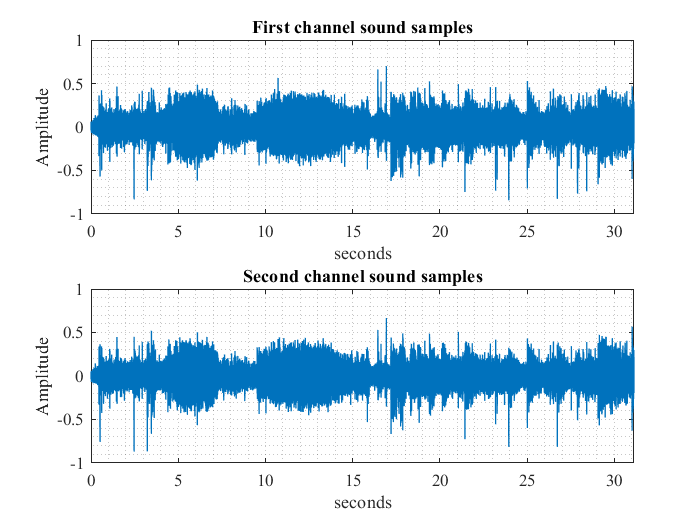

% Evidence handling and Initial assessment

% Waveform view
ShowWaveform(samples, fsample);

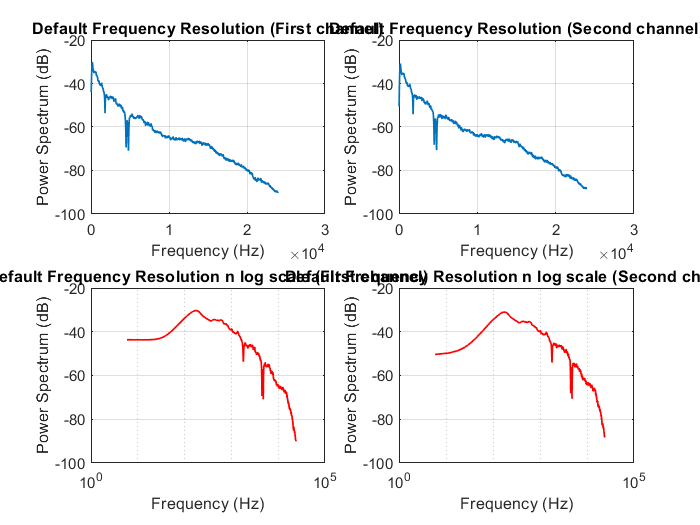


% PSD view
ShowPSD2(samples, fsample);


% Spectrogram view
% ShowSpectrogram(samples, fsample);

% Statistical view
audioStats(samples, fsample);

Max value in first Channel = 0.69904
Max value in second Channel = 0.66599
Minimum value in first Channel = -0.84174
Minimum value in second Channel = -0.86951
Mean value in first channel = 4.5063e-05
Mean value in second channel= -3.7286e-05
standard deviation of first channel= 0.096548
standard deviation of second channel= 0.089689
Variance of first channel= 0.0093216
Variance of second channel= 0.0080442
Power in first channel in dB= -20.3051
Power in second channel in dB= -20.9452
Sampling frequency in Hz =48000


% Audio feactures (MFCC)

% Mel Frequency capstral coefficient

[coeff, delta, deltaDelta, logf] = mfcc(samples, fsample);



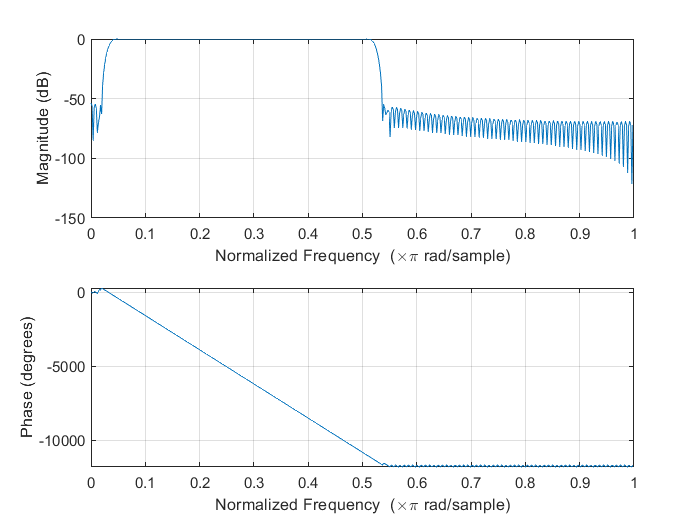

% Audio Enhancement techniques

% bandpass filter 
order =256;
resultAudio = bandpassVocalFilter(samples, order,fsample, 0.8);

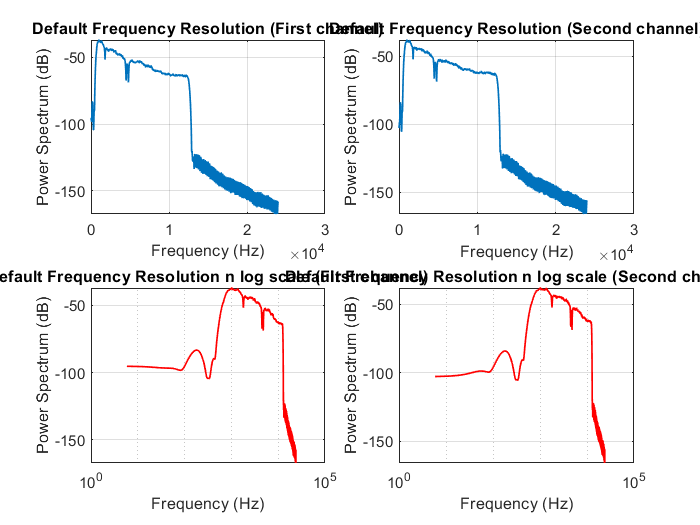


player = audioplayer(resultAudio, fsample);
play(player);

ShowPSD2(resultAudio, fsample);

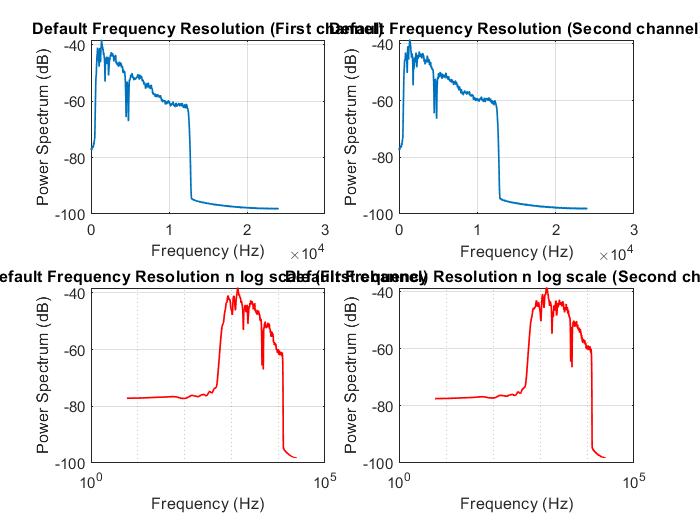


% Wiener filter approach

resultAudio2 = wienerFilter(resultAudio, fsample, 0.25);

player = audioplayer(resultAudio2, fsample);
play(player);

ShowPSD2(resultAudio2, fsample);

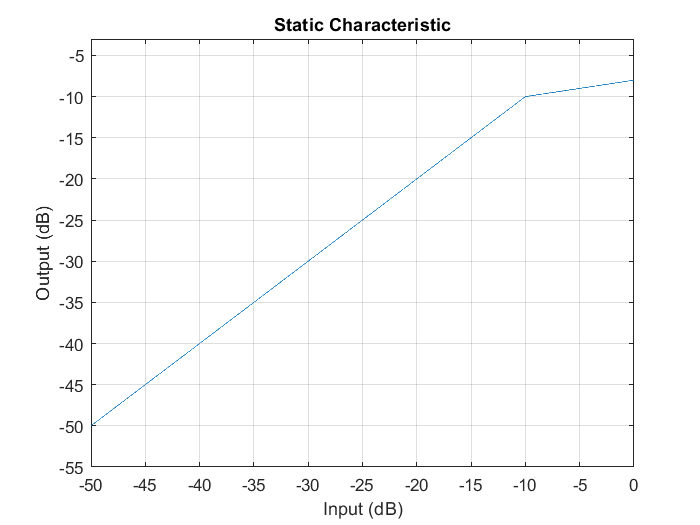

% Compressor 

dRC = compressor(-10,5,'SampleRate',fsample);
visualize(dRC)

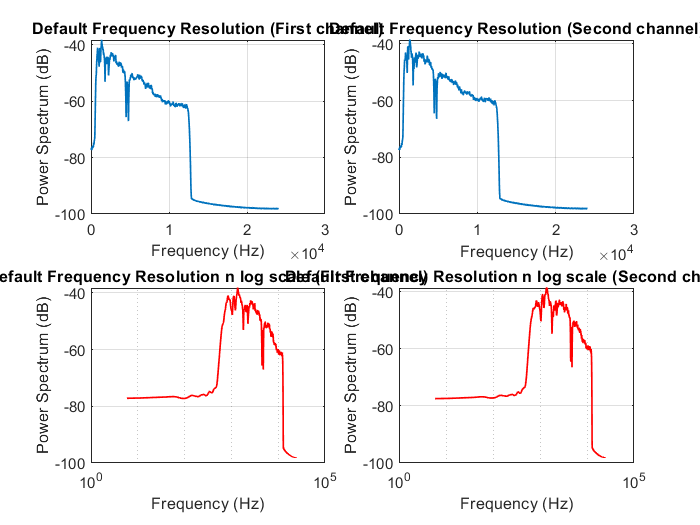


resultAudio3 = dRC(resultAudio2);

player = audioplayer(resultAudio3, fsample);
play(player);

ShowPSD2(resultAudio3, fsample);

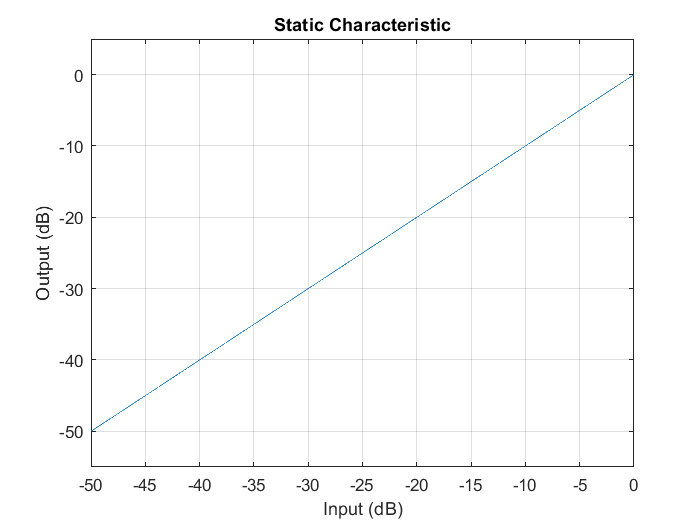

% Expender

dRC = expander(-65, 5, 'SampleRate',fsample);
visualize(dRC);

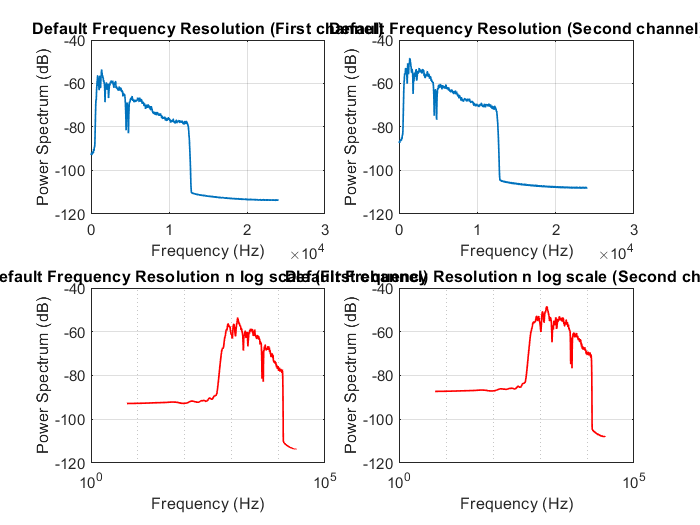


resultAudio4 = dRC(resultAudio3);


player = audioplayer(resultAudio4, fsample);
play(player);

ShowPSD2(resultAudio4, fsample);

% Audio Writting

audiowrite('enhancedTestAudio1.wav', resultAudio4, fsample);
